% Define file and sheet names to include
filename = 'Solar_WPT_Results.xlsx';
sheetsToPlot = {'T41', 'T42', 'T43', 'T44'};  % Replace with sheet names to plot

% Create a figure
figure;

% To have different colors for each sheet
colors = lines(length(sheetsToPlot));

% Hold for overlaying all curves
hold on;
yyaxis left;

for i = 1:length(sheetsToPlot)
    % Automatically detects headers and data
    data = readtable(filename, 'Sheet', sheetsToPlot{i});
    
    % Extracts Voltage and Current
    V = data.Voltage;
    I = data.Current;
    
    % Cleans NaNs if any
    validIdx = ~isnan(V) & ~isnan(I);
    V = V(validIdx);
    I = I(validIdx);
    
    % Plots IV curve
    plot(V, I, '-', 'Color', colors(i,:), 'LineWidth', 2, ...
         'DisplayName', [sheetsToPlot{i} ' - IV']);
end


ylabel('Current (A)', 'FontSize', 14);

% Starts plotting PV curve on right axis
yyaxis right;

for i = 1:length(sheetsToPlot)
    data = readtable(filename, 'Sheet', sheetsToPlot{i});
    
    V = data.Voltage;
    I = data.Current;
    P = V .* I;
    
    % Cleans NaNs
    validIdx = ~isnan(V) & ~isnan(I);
    V = V(validIdx);
    P = P(validIdx);
    
    % Plots PV curve
    plot(V, P, '--', 'Color', colors(i,:), 'LineWidth', 2, ...
         'DisplayName', [sheetsToPlot{i} ' - PV']);
end

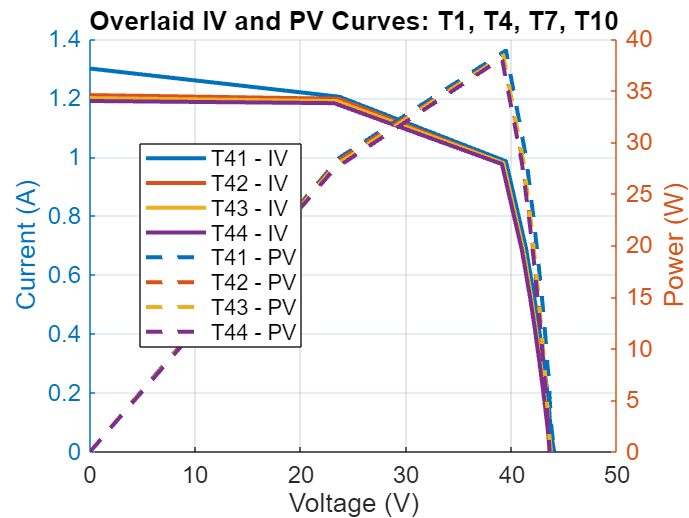


xlabel('Voltage (V)', 'FontSize', 14);
ylabel('Power (W)', 'FontSize', 14);
title('Overlaid IV and PV Curves: T1, T4, T7, T10', 'FontSize', 16);
legend('Location', 'best');
grid on;
set(gca, 'FontSize', 12);
hold off;